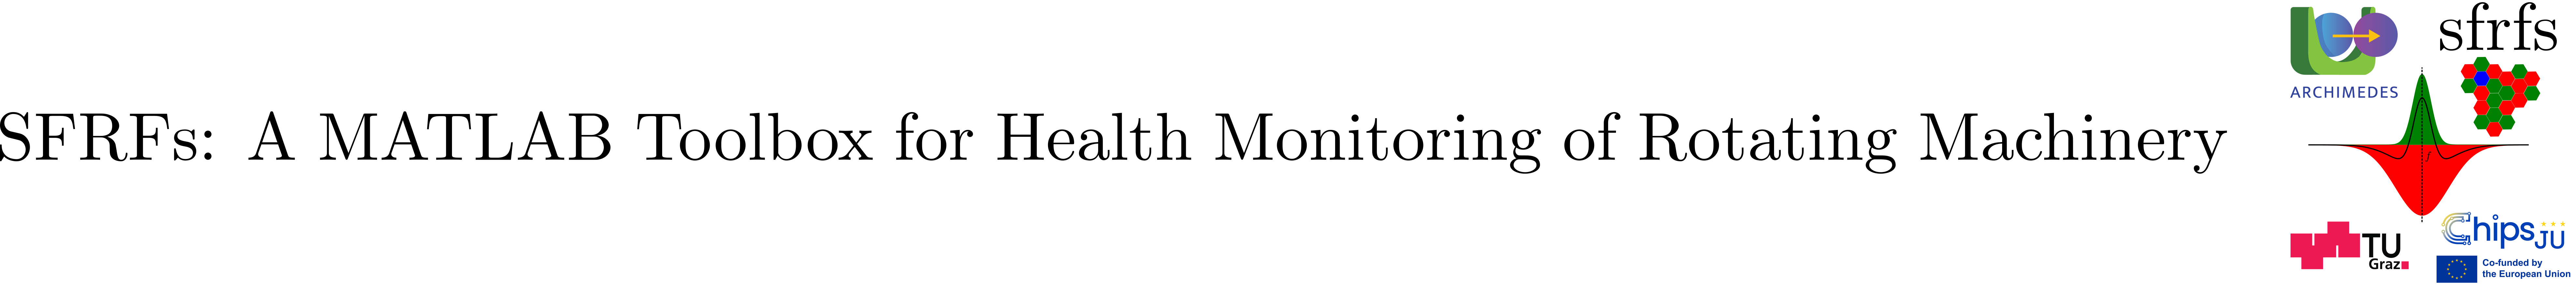

# OperatingConditionsTableSchema

## Summary

`OperatingConditionsTableSchema` defines column name constants for operating-condition tables.

## Description

Operating-condition tables represent the independent variables along which diagnostic knowledge and perceptual artifacts are evaluated.

This schema centralizes the column names used by `OperatingConditions.conditionsTable`, ensuring stable access to speed and load axes across the toolbox.

### Defined columns

### Notes

- This schema defines *independent variables* for fault-band computation and SFRF evaluation.

- It is consumed by `FaultFrequencyBands` and propagated through downstream schema layers.

### See also

[`OperatingConditions`](matlab:open('./OperatingConditions.mlx')), [tables.`FaultBandsTableSchema`](matlab:open('./FaultBandsTableSchema.mlx')), [tables.`GainFunctionsTableSchema`](matlab:open('./GainFunctionsTableSchema.mlx'))

## `Example`

% Example: construct an operating-conditions table using schema keys

import tables.OperatingConditionsTableSchema

T = table();
T.(OperatingConditionsTableSchema.SPEED) = [35; 37.5; 40];
T.(OperatingConditionsTableSchema.LOAD)  = [12; 11; 10];

disp("Columns: " + strjoin(string(T.Properties.VariableNames), ", "));

Columns: Speed, Load


disp(T);

    Speed    Load
    _____    ____

      35      12 
    37.5      11 
      40      10 



## API documentation

### MATLAB help

help tables.OperatingConditionsTableSchema

  OperatingConditionsTableSchema  Column name constants for operating
  conditions tables
 
  This schema centralizes column name constants used by
  OperatingConditions.conditionsTable.
 
  See also OperatingConditions

    Documentation for tables.OperatingConditionsTableSchema



## Source code

The source of the class can be found in [OperatingConditionsTableSchema](matlab:open('../../+tables/OperatingConditionsTableSchema.m')).

## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1-9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025) [DOI:10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9).